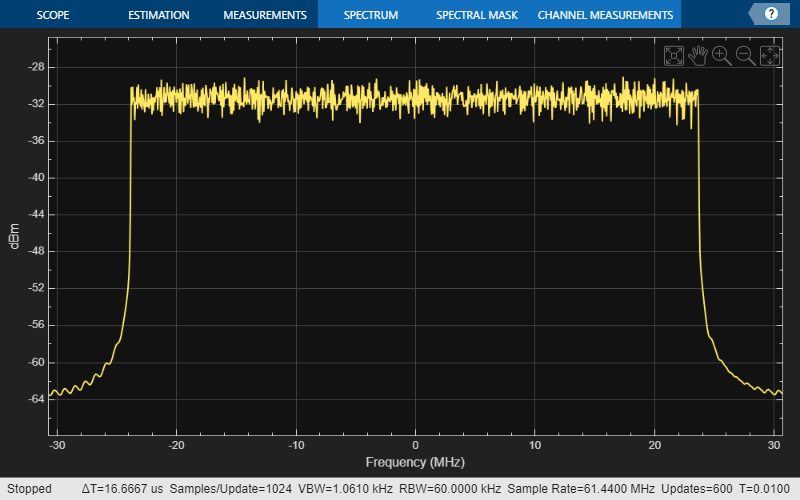

% Generated by MATLAB(R) 24.2 (R2024b) and 5G Toolbox 24.2 (R2024b).
% Generated on: 04-Feb-2025 01:48:16

%% Generating Downlink FRC waveform
% Downlink FRC configuration
cfgDLFRC = nrDLCarrierConfig;
cfgDLFRC.Label = 'DL-FRC-FR2-16QAM';
cfgDLFRC.FrequencyRange = 'FR2';
cfgDLFRC.ChannelBandwidth = 50;
cfgDLFRC.NCellID = 1;
cfgDLFRC.NumSubframes = 10;
cfgDLFRC.InitialNSubframe = 0;
cfgDLFRC.WindowingPercent = 0;
cfgDLFRC.SampleRate = [];
cfgDLFRC.CarrierFrequency = 0;

%% SCS specific carriers
% Carrier 1
scscarrier1 = nrSCSCarrierConfig;
scscarrier1.SubcarrierSpacing = 60;
scscarrier1.NSizeGrid = 66;
scscarrier1.NStartGrid = 0;

% Carrier 2
scscarrier2 = nrSCSCarrierConfig;
scscarrier2.SubcarrierSpacing = 120;
scscarrier2.NSizeGrid = 21;
scscarrier2.NStartGrid = 6;

cfgDLFRC.SCSCarriers = {scscarrier1,scscarrier2};

%% Bandwidth Parts
bwp = nrWavegenBWPConfig;
bwp.BandwidthPartID = 1;
bwp.Label = 'BWP1';
bwp.SubcarrierSpacing = 60;
bwp.CyclicPrefix = 'normal';
bwp.NSizeBWP = 66;
bwp.NStartBWP = 0;

cfgDLFRC.BandwidthParts = {bwp};

%% Synchronization Signals Burst
ssburst = nrWavegenSSBurstConfig;
ssburst.Enable = true;
ssburst.Power = 0;
ssburst.BlockPattern = 'Case D';
ssburst.TransmittedBlocks = [1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0];
ssburst.Period = 10;
ssburst.NCRBSSB = [];
ssburst.KSSB = 0;
ssburst.DataSource = 'MIB';
ssburst.DMRSTypeAPosition = 2;
ssburst.CellBarred = false;
ssburst.IntraFreqReselection = false;
ssburst.PDCCHConfigSIB1 = 0;
ssburst.SubcarrierSpacingCommon = 60;

cfgDLFRC.SSBurst = ssburst;

%% CORESET and Search Space Configuration
coreset = nrCORESETConfig;
coreset.CORESETID = 1;
coreset.Label = 'CORESET1';
coreset.FrequencyResources = ones([1 11]);
coreset.Duration = 2;
coreset.CCEREGMapping = 'noninterleaved';
coreset.REGBundleSize = 6;
coreset.InterleaverSize = 2;
coreset.ShiftIndex = 0;
coreset.PrecoderGranularity = 'sameAsREG-bundle';
coreset.RBOffset = [];

cfgDLFRC.CORESET = {coreset};

% Search Spaces
searchspace = nrSearchSpaceConfig;
searchspace.SearchSpaceID = 1;
searchspace.Label = 'SearchSpace1';
searchspace.CORESETID = 1;
searchspace.SearchSpaceType = 'common';
searchspace.StartSymbolWithinSlot = 0;
searchspace.SlotPeriodAndOffset = [1 0];
searchspace.Duration = 1;
searchspace.NumCandidates = [8 8 4 2 1];

cfgDLFRC.SearchSpaces = {searchspace};

%% PDCCH Instances Configuration
pdcch = nrWavegenPDCCHConfig;
pdcch.Enable = false;
pdcch.Label = 'PDCCH1';
pdcch.Power = 0;
pdcch.BandwidthPartID = 1;
pdcch.SearchSpaceID = 1;
pdcch.AggregationLevel = 1;
pdcch.AllocatedCandidate = 1;
pdcch.CCEOffset = [];
pdcch.SlotAllocation = 1:39;
pdcch.Period = 40;
pdcch.Coding = false;
pdcch.DataBlockSize = 20;
pdcch.DataSource = 0;
pdcch.RNTI = 0;
pdcch.DMRSScramblingID = 1;
pdcch.DMRSPower = 0;

cfgDLFRC.PDCCH = {pdcch};

%% PDSCH Instances Configuration
% PDSCH 1
pdsch1 = nrWavegenPDSCHConfig;
pdsch1.Enable = true;
pdsch1.Label = 'Full-band PDSCH sequence';
pdsch1.Power = 0;
pdsch1.BandwidthPartID = 1;
pdsch1.Modulation = '16QAM';
pdsch1.NumLayers = 1;
pdsch1.MappingType = 'A';
pdsch1.ReservedCORESET = [];
pdsch1.SymbolAllocation = [2 12];
pdsch1.SlotAllocation = 1:39;
pdsch1.Period = 40;
pdsch1.PRBSet = 0:65;
pdsch1.PRBSetType = 'VRB';
pdsch1.VRBToPRBInterleaving = false;
pdsch1.VRBBundleSize = 2;
pdsch1.NID = [];
pdsch1.RNTI = 0;
pdsch1.Coding = true;
pdsch1.TargetCodeRate = 0.478515625;
pdsch1.TBScaling = 1;
pdsch1.XOverhead = 0;
pdsch1.LimitedBufferRateMatching = true;
pdsch1.MaxNumLayers = 8;
pdsch1.MCSTable = 'qam64';
pdsch1.RVSequence = 0;
pdsch1.DataSource = 'PN9';
pdsch1.DMRSPower = 3;
pdsch1.EnablePTRS = false;
pdsch1.PTRSPower = 0;

% PDSCH Reserved PRB
pdsch1ReservedPRB = nrPDSCHReservedConfig;
pdsch1ReservedPRB.PRBSet = [];
pdsch1ReservedPRB.SymbolSet = [];
pdsch1ReservedPRB.Period = [];

pdsch1.ReservedPRB = {pdsch1ReservedPRB};

% PDSCH DM-RS
pdsch1DMRS = nrPDSCHDMRSConfig;
pdsch1DMRS.DMRSConfigurationType = 1;
pdsch1DMRS.DMRSReferencePoint = 'CRB0';
pdsch1DMRS.DMRSTypeAPosition = 2;
pdsch1DMRS.DMRSAdditionalPosition = 2;
pdsch1DMRS.DMRSLength = 1;
pdsch1DMRS.CustomSymbolSet = [];
pdsch1DMRS.DMRSPortSet = [];
pdsch1DMRS.NIDNSCID = [];
pdsch1DMRS.NSCID = 0;
pdsch1DMRS.NumCDMGroupsWithoutData = 2;
pdsch1DMRS.DMRSDownlinkR16 = false;
pdsch1DMRS.DMRSEnhancedR18 = false;

pdsch1.DMRS = pdsch1DMRS;

% PDSCH PT-RS
pdsch1PTRS = nrPDSCHPTRSConfig;
pdsch1PTRS.TimeDensity = 1;
pdsch1PTRS.FrequencyDensity = 2;
pdsch1PTRS.REOffset = '00';
pdsch1PTRS.PTRSPortSet = [];

pdsch1.PTRS = pdsch1PTRS;

% PDSCH 2
pdsch2 = nrWavegenPDSCHConfig;
pdsch2.Enable = true;
pdsch2.Label = 'Data Region OCNG for BWP 1, PRBs 0:65, symbols 0:13, slot 0';
pdsch2.Power = 0;
pdsch2.BandwidthPartID = 1;
pdsch2.Modulation = 'QPSK';
pdsch2.NumLayers = 1;
pdsch2.MappingType = 'A';
pdsch2.ReservedCORESET = [];
pdsch2.SymbolAllocation = [0 14];
pdsch2.SlotAllocation = 0;
pdsch2.Period = 40;
pdsch2.PRBSet = 0:65;
pdsch2.PRBSetType = 'VRB';
pdsch2.VRBToPRBInterleaving = false;
pdsch2.VRBBundleSize = 2;
pdsch2.NID = 2;
pdsch2.RNTI = 2;
pdsch2.Coding = false;
pdsch2.TargetCodeRate = 0.513671875;
pdsch2.TBScaling = 1;
pdsch2.XOverhead = 0;
pdsch2.LimitedBufferRateMatching = true;
pdsch2.MaxNumLayers = 8;
pdsch2.MCSTable = 'qam256';
pdsch2.RVSequence = [0 2 3 1];
pdsch2.DataSource = 'PN9';
pdsch2.DMRSPower = 0;
pdsch2.EnablePTRS = false;
pdsch2.PTRSPower = 0;

pdschreserved = nrPDSCHReservedConfig;
pdschreserved.PRBSet = [];
pdschreserved.SymbolSet = [];
pdschreserved.Period = [];

pdsch2.ReservedPRB = {pdschreserved};

pdschdmrs = nrPDSCHDMRSConfig;
pdschdmrs.DMRSConfigurationType = 1;
pdschdmrs.DMRSReferencePoint = 'CRB0';
pdschdmrs.DMRSTypeAPosition = 2;
pdschdmrs.DMRSAdditionalPosition = 2;
pdschdmrs.DMRSLength = 1;
pdschdmrs.CustomSymbolSet = [];
pdschdmrs.DMRSPortSet = [];
pdschdmrs.NIDNSCID = [];
pdschdmrs.NSCID = 0;
pdschdmrs.NumCDMGroupsWithoutData = 2;
pdschdmrs.DMRSDownlinkR16 = false;
pdschdmrs.DMRSEnhancedR18 = false;

pdsch2.DMRS = pdschdmrs;

pdschptrs = nrPDSCHPTRSConfig;
pdschptrs.TimeDensity = 1;
pdschptrs.FrequencyDensity = 2;
pdschptrs.REOffset = '00';
pdschptrs.PTRSPortSet = [];

pdsch2.PTRS = pdschptrs;

% PDSCH 3
pdsch3 = nrWavegenPDSCHConfig;
pdsch3.Enable = true;
pdsch3.Label = 'Data Region OCNG for BWP 1, PRBs 0:65, symbols 0:1, slots 1:39';
pdsch3.Power = 0;
pdsch3.BandwidthPartID = 1;
pdsch3.Modulation = 'QPSK';
pdsch3.NumLayers = 1;
pdsch3.MappingType = 'B';
pdsch3.ReservedCORESET = [];
pdsch3.SymbolAllocation = [0 2];
pdsch3.SlotAllocation = 1:39;
pdsch3.Period = 40;
pdsch3.PRBSet = 0:65;
pdsch3.PRBSetType = 'VRB';
pdsch3.VRBToPRBInterleaving = false;
pdsch3.VRBBundleSize = 2;
pdsch3.NID = 2;
pdsch3.RNTI = 2;
pdsch3.Coding = false;
pdsch3.TargetCodeRate = 0.513671875;
pdsch3.TBScaling = 1;
pdsch3.XOverhead = 0;
pdsch3.LimitedBufferRateMatching = true;
pdsch3.MaxNumLayers = 8;
pdsch3.MCSTable = 'qam256';
pdsch3.RVSequence = [0 2 3 1];
pdsch3.DataSource = 'PN9';
pdsch3.DMRSPower = 0;
pdsch3.EnablePTRS = false;
pdsch3.PTRSPower = 0;

pdschreserved = nrPDSCHReservedConfig;
pdschreserved.PRBSet = [];
pdschreserved.SymbolSet = [];
pdschreserved.Period = [];

pdsch3.ReservedPRB = {pdschreserved};

pdschdmrs = nrPDSCHDMRSConfig;
pdschdmrs.DMRSConfigurationType = 1;
pdschdmrs.DMRSReferencePoint = 'CRB0';
pdschdmrs.DMRSTypeAPosition = 2;
pdschdmrs.DMRSAdditionalPosition = 0;
pdschdmrs.DMRSLength = 1;
pdschdmrs.CustomSymbolSet = [];
pdschdmrs.DMRSPortSet = [];
pdschdmrs.NIDNSCID = [];
pdschdmrs.NSCID = 0;
pdschdmrs.NumCDMGroupsWithoutData = 2;
pdschdmrs.DMRSDownlinkR16 = false;
pdschdmrs.DMRSEnhancedR18 = false;

pdsch3.DMRS = pdschdmrs;

pdschptrs = nrPDSCHPTRSConfig;
pdschptrs.TimeDensity = 1;
pdschptrs.FrequencyDensity = 2;
pdschptrs.REOffset = '00';
pdschptrs.PTRSPortSet = [];

pdsch3.PTRS = pdschptrs;

cfgDLFRC.PDSCH = {pdsch1,pdsch2,pdsch3};

%% CSI-RS Instances Configuration
csirs = nrWavegenCSIRSConfig;
csirs.Enable = false;
csirs.Label = 'CSIRS1';
csirs.Power = 0;
csirs.BandwidthPartID = 1;
csirs.CSIRSType = 'nzp';
csirs.CSIRSPeriod = 'on';
csirs.RowNumber = 3;
csirs.Density = 'one';
csirs.SymbolLocations = 0;
csirs.SubcarrierLocations = 0;
csirs.NumRB = 66;
csirs.RBOffset = 0;
csirs.NID = 1;

cfgDLFRC.CSIRS = {csirs};

% Generation
[waveform,info] = nrWaveformGenerator(cfgDLFRC);

Fs = info.ResourceGrids(1).Info.SampleRate; 								 % Specify the sample rate of the waveform in Hz

%% Visualize
% Spectrum Analyzer
spectrum = spectrumAnalyzer('SampleRate', Fs);
spectrum(waveform);
release(spectrum);